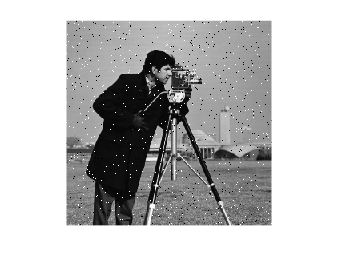

% Create Image 
I = imread('cameraman.tif');

%add salt and pepper noise 
noisyImage = imnoise(I,"salt & pepper",0.02);

imshow(noisyImage)

% Filtering Techniques 

%Median Filter
medianFiltered = medfilt2(noisyImage,[3,3]);

medianFiltered = 256×256 uint8 matrix
     0   156   155   157   156   157   158   158   158   157   156   155   156     0   157   157   158   161   159   160   160   161   161   161   161   161   162   163   163   162   162   163   164   163   163   163   164   165   165   165   164   164   164   167   166   167   167   169   168   169
   156   158   158   158   157   158   158   158   158   158   158   158   159   160   158   160   161   162   161   162   160   162   163   163   163   161   163   164   164   165   165   165   165   165   165   165   165   166   166   165   165   165   166   169   167   167   168   169   169   169
   154   157   157   157   158   158   158   158   158   158   158   159   159   160   158   160   159   161   160   161   162   162   162   161   162   161   163   164   164   165   165   165   164   163   163   163   165   167   167   165   164   164   169   169   169   169   169   170   169   170
   154   156   155   158   158   158   158   158   158   15


%Gaussian filter
h = fspecial('gaussian',[3,3],1.5) % Gaussian Kernel

h =     0.0947    0.1183    0.0947
    0.1183    0.1478    0.1183
    0.0947    0.1183    0.0947


gaussianFiltered = imfilter(noisyImage,h);

gaussianFiltered = 256×256 uint8 matrix
    75   109   109   109   109   109   109   109   109   109   109    90    86    73    86    92   111   112   111   122   125   123   112   112   112   112   113   113   113   114   114   114   114   114   114   114   114   115   115   115   114   123   126   125   100    97   101   117   117   117
   109   157   157   157   157   158   158   158   158   158   158   143   140   129   140   145   161   162   160   170   172   171   162   162   162   162   163   163   164   173   175   173   149   145   149   164   165   166   166   165   164   176   180   178   148   143   149   169   169   169
   109   142   138   142   157   158   158   158   158   167   169   167   159   159   159   160   161   162   160   161   161   162   162   162   146   143   148   164   164   176   179   176   145   140   144   148   146   151   166   165   164   174   177   177   152   149   153   169   169   169
   108   138   133   139   157   157   157   157   157   


%Wiener Filter

wienerFiltered = wiener2(noisyImage, [5 5]);

originalImage = imread('cameraman.tif');  % Original image
psnrMedian = psnr(medianFiltered, originalImage);
mseMedian = immse(medianFiltered, originalImage);

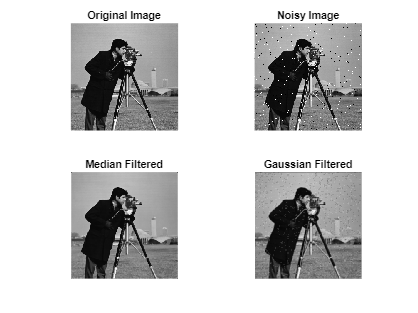

figure;
subplot(2,2,1), imshow(I), title('Original Image');
subplot(2,2,2), imshow(noisyImage), title('Noisy Image');
subplot(2,2,3), imshow(medianFiltered), title('Median Filtered');
subplot(2,2,4), imshow(gaussianFiltered), title('Gaussian Filtered');

% Load the original image
originalImage = imread('cameraman.tif');  % Original image
noisyImage = imnoise(originalImage, 'salt & pepper', 0.02);  % Add noise

% Apply the filters
medianFiltered = medfilt2(noisyImage, [3 3]);
h = fspecial('gaussian', [3 3], 1.5);
gaussianFiltered = imfilter(noisyImage, h);
wienerFiltered = wiener2(noisyImage, [5 5]);

% Calculate PSNR and MSE for Median Filter
psnrMedian = psnr(medianFiltered, originalImage);
mseMedian = immse(medianFiltered, originalImage);

% Calculate PSNR and MSE for Gaussian Filter
psnrGaussian = psnr(gaussianFiltered, originalImage);
mseGaussian = immse(gaussianFiltered, originalImage);

% Calculate PSNR and MSE for Wiener Filter
psnrWiener = psnr(wienerFiltered, originalImage);
mseWiener = immse(wienerFiltered, originalImage);

% Display the results
fprintf('Median Filter: PSNR = %.2f, MSE = %.2f\n', psnrMedian, mseMedian);

Median Filter: PSNR = 27.00, MSE = 129.78


fprintf('Gaussian Filter: PSNR = %.2f, MSE = %.2f\n', psnrGaussian, mseGaussian);

Gaussian Filter: PSNR = 24.66, MSE = 222.23


fprintf('Wiener Filter: PSNR = %.2f, MSE = %.2f\n', psnrWiener, mseWiener);

Wiener Filter: PSNR = 25.43, MSE = 186.27
